# Plot Traces from Task

clear

% input information for finding data
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );
task      = '04_Tactile_Spatial_Suppression';
beapp_tag = '_25hzLP_32hzNF';
fig_path  = fullfile(data_path,task,'figures');

% input channel(s) and other parameters to create plot
chan_1020    = {'C3'};
chan_other   = [30 41];
chan_weights = [ ];
exclude      = {''};  % ids of subjects to exclude
trial_thresh = 10;
save_fig     = false;  % save figures?
use_happe    = false;  % load data from HAPPE+ER path (vs. segment folder)  
use_median   = false;  % use median (rather than mean) to create plot
norm_data    = false;  % normalize subject data before averaging
norm_type    = 'medianiqr';  % type of normalization to use (see matlab 'normalize')

% input time range and other parameters for plot format
conds_to_plot = 1:3;
cond_names    = {'Index','Middle','Both'};
group_names   = {'TD','ASD','SPD'};
% colors        = {[0 0 0],[0.25 0.25 0.25],[0.5 0.5 0.5],[0.75 0.75 0.75]};
% colors        = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250]};
colors        = {[0 0.4470 0.7410],[0.1961 0.6588 0.3216],[0.8500 0.3250 0.0980]};
% colors        = flip(colors);
time_range    = [-100 500];  % time range to show on plot
times_to_plot = [-100:50:500];  % times to label on plot
fig_size      = [150 150 800 350];  % [x y width height]
ylims   = [-10 10];
x_label = 'Time (ms)';
y_label = 'Amplitude (\muV)';

### Compile task data and sort into groups

% get paths for loading data
grp_label_path = fullfile(data_path,'01_Subject_Info_for_Processing','Group_Assignments.mat');
gpi_path = ['out' beapp_tag filesep 'Run_Report_Variables_and_Settings' ...
                                     beapp_tag '.mat'];
load([data_path filesep task filesep gpi_path])
gpi = grp_proc_info;
clear grp_proc_info

% load group information
load(grp_label_path,'groups')
ids = setdiff(groups.id,exclude);

% get segmentation window
seg_win = [gpi.evt_seg_win_start gpi.evt_seg_win_end] * 1000;
n_samples = ceil(1000 * sum(abs(seg_win))/1000);

% generate times for x-axis
times = round(linspace(seg_win(1),seg_win(2),n_samples));

% load and plot data
if use_happe, seg_folder = 'HAPPE_V3'; else seg_folder = 'segment'; end
data_dir = dir(fullfile(data_path,task,[seg_folder  beapp_tag],'*.mat'));
n_files = size(data_dir,1);
conds_i = 1:length(conds_to_plot);
grand_avg = cell(length(conds_to_plot),length(group_names));
for i_f = 1:n_files
    file = data_dir(i_f);
    load([file.folder filesep file.name],'eeg_w')
    chan_str = get_chan_str(chan_1020,chan_other);
    
    % get subject group
    subject  = file.name(1:4);
    s_idx  = strcmp(groups.id,subject);
    grp_id = groups.group(s_idx);
    min_trials = min(cellfun('size',eeg_w,3));
    if isempty(grp_id) || sum(strcmp(exclude,subject)) > 0 || min_trials < trial_thresh || grp_id > length(group_names)
        continue
    end
    
    trace = trace_to_matrix(eeg_w, chan_1020, chan_other, chan_weights, use_median);
    if max(trace,[],'all') < 1e-6, continue; end
    if norm_data
        trace = normalize(trace',norm_type)';
    end
    
    % save traces of selected conditions
    for i_c = conds_i
        grand_avg{i_c,grp_id}(end+1,:) = trace(conds_to_plot(i_c),:);
    end
end

% set y limits and updated beapp tag for normalized data
if norm_data
    ylims = [-2 2];
    beapp_tag = [beapp_tag '_norm'];
end

### Create condition average plots

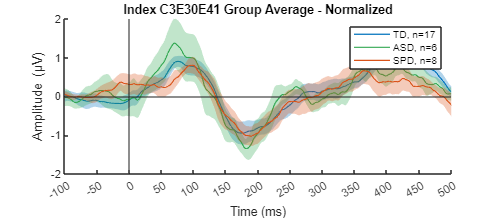

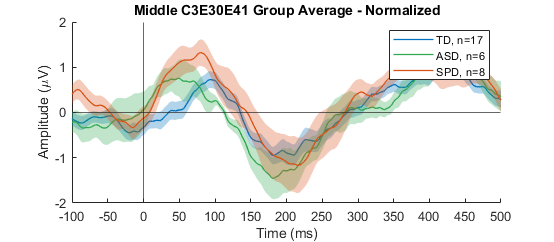

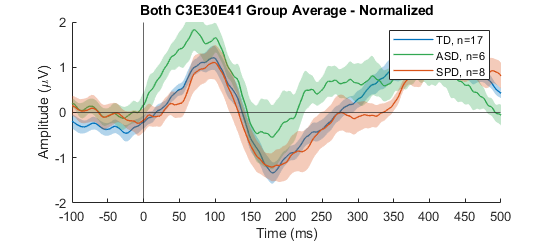

% get string of channels used, number of groups for plotting
chan_str = get_chan_str(chan_1020,chan_other);
n_grps   = length(group_names);

%% create average waveform plots for each condition
for i_c = conds_i
    % prepare figure
    cond = cond_names{i_c};
    titl = [cond ' ' chan_str ' Group Average']; 
    if norm_data, titl = [titl ' - Normalized']; end
    f = prep_fig(fig_size,titl,x_label,y_label,times_to_plot,time_range);
    
    % add group data
    for i_g = 1:n_grps
        n_subjs = size(grand_avg{1,i_g},1);

        % calculate group mean and SE
        grp_data = grand_avg{i_c,i_g};
        grp_mean = squeeze(mean(grp_data,1,'omitnan'));
        grp_SE   = std(grp_data,0,1,'omitnan')/sqrt(n_subjs);
        
        % get & plot confidence intervals
        xconf = [times times(end:-1:1)];
        yconf = [grp_mean+grp_SE grp_mean(end:-1:1)-grp_SE(end:-1:1)];
        ci = fill(xconf,yconf,colors{i_g},'FaceAlpha',0.3);
        ci.EdgeColor = 'none';

        % plot average
        plot(times,grp_mean,'linewidth',1,'color',colors{i_g})
    end
    xline(0,'DisplayName','t = 0 ms');
    yline(0,'DisplayName','y = 0 \muV');
    ylim(ylims)
    
    % generate legend
    legend_names = cell(1,n_grps*2);
    for i_g = 1:n_grps
        legend_names{2*i_g-1} = '';
        legend_names{2*i_g} = [group_names{i_g} ', n=' int2str(size(grand_avg{1,i_g},1))];
    end
    legend(legend_names)
    
    % save figures
    if save_fig
        fig_path_trace = fullfile(fig_path,'traces_by_condition');
        if ~exist(fig_path_trace,'dir')
            mkdir(fig_path_trace)
        end
        fig_fname = [cond '_' chan_str beapp_tag '_' get_date_str()];
        saveas(f,fullfile(fig_path_trace,fig_fname),'jpg')
    end
end

### For TSS: plot Both:(Index+Middle) ratio time series

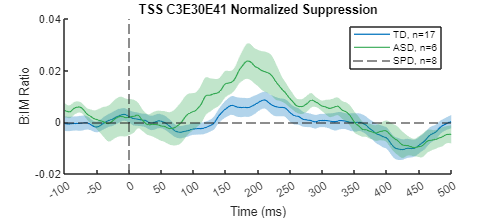

if strcmp(task,'04_Tactile_Spatial_Suppression')

% prepare figure, labels
if norm_data
    titl = ['TSS ' chan_str ' Normalized Suppression'];
else
    titl = ['TSS ' chan_str ' Suppression'];
end
f = prep_fig(fig_size,titl,x_label,'B:IM Ratio',times_to_plot,time_range);

% compute normalized, thresholded ratio
for i_g = 1:2%n_grps
    % get each condition group average power
    grp_n    = size(grand_avg{1,i_g},1);
    grp_im   = grand_avg{1,i_g} + grand_avg{2,i_g};
    grp_both = grand_avg{3,i_g};
%     max_amp  = max(abs([grp_im grp_both]),[],'all');
   
    % calculate percent change (with all positive amplitudes)
    grp_pc = (grp_both - grp_im)./(grp_im+100);%max_amp); 
    % calculate percent change (in freq domain)
%     grp_pc = norm_b_by_im(grp_im,grp_both);
%     grp_pc_z = abs(zscore(grp_pc')');
%     grp_pc(grp_pc_z > 2) = NaN;
    
    % find standard error
    grp_SE = std(grp_pc,0,1,'omitnan') / sqrt(grp_n);

    % get group average ratio
    grp_pc = mean(grp_pc,1,'omitnan');
%     grp_pc = smooth(grp_pc)';

    % plot confidence intervals
    xconf = [times times(end:-1:1)];
    yconf = [grp_pc+grp_SE grp_pc(end:-1:1)-grp_SE(end:-1:1)];
    ci = fill(xconf,smooth(yconf),colors{i_g},'FaceAlpha',0.3);
    ci.EdgeColor = 'none';
    % plot group average ratio
    plot(times,grp_pc,'linewidth',1,'color',colors{i_g})
end
xline(0,'--','DisplayName','t = 0 ms');
yline(0,'--','DisplayName','y = 0 \muV');
legend(legend_names)

% save figures
if save_fig
    % get and create file path, if necessary
    fig_path_tssr = fullfile(fig_path,'tss_ratios');
    if ~exist(fig_path_tssr,'dir')
        mkdir(fig_path_tssr)
    end

    % get figure name and save
    if weigh_tss_rt, fig_fname = ['tss_ratio_weighted_' chan_str beapp_tag '_' get_date_str()];
    else, fig_fname = ['tss_ratio_' chan_str beapp_tag]; end
    saveas(f,fullfile(fig_path_tssr,fig_fname),'jpg')
end

end

### Helper functions

function f = prep_fig(fig_size,titl,x_lab,y_lab,x_ticks,x_lim)
    % create_figure
    f = figure('Position',fig_size);
    hold on
    legend show
    title(titl)
    xlabel(x_lab)
    ylabel(y_lab)
    
    % adjust x-axis
    xticks(x_ticks)
    xlim(x_lim)
end

function cr = norm_b_by_im(grp_im,grp_both)
    imX = fft(grp_im); % nConvolution-point FFT
    bX  = fft(grp_both);
    pct_change = (bX - imX)./imX; 
    cr = ifft( pct_change ); % convolution result
end

function ts_signs = get_ts_signs(ts)
    [m,n] = size(ts);
    ts_signs = zeros(m,n);
    for i_r = 1:m
        for i_c = 1:n
            if ts(i_r,i_c) > 0, ts_signs(i_r,i_c) = 1;
            elseif ts(i_r,i_c) < 0, ts_signs(i_r,i_c) = -1; end
        end
    end
end